#    ROS Actions and the UR Robot

The [ActionServer](http://wiki.ros.org/actionlib)[ & ](http://wiki.ros.org/actionlib)[ActionClient](http://wiki.ros.org/actionlib) is the 3rd fundamental mode to communicate in ROS. It is similar to services.

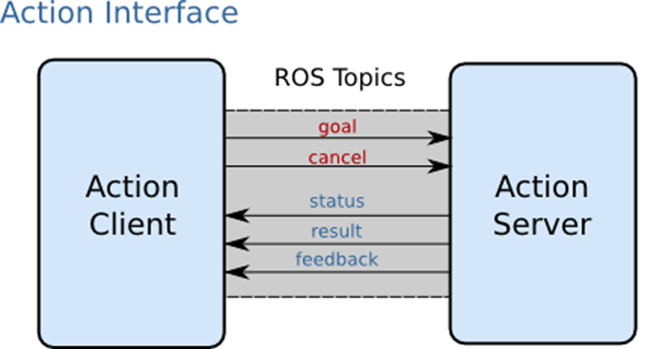

The approach is **non-blocking **and useful for behavior that take long periods of time such as: 

- Navigation

- Manipulation ( typically used to execute manipulation tasks using time-stamped joint poses).

# 0. Connect to the Simulation

We will open up the UR simulation in gazebo.

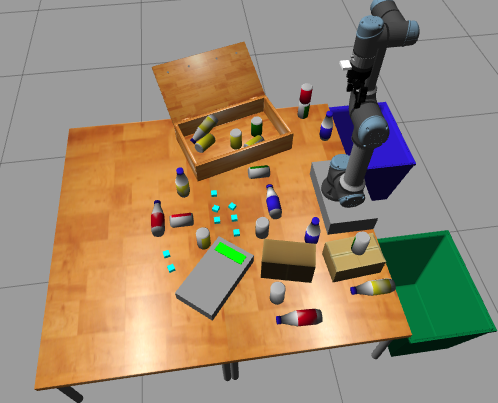

### 0.1 Run your Virtual Machine

To this end, you will need to run your virtual machine and start the armgazebo container. 

### 0.2 Run your Container

Remember to call run.bash from inside src/arm_gazebo/docker:

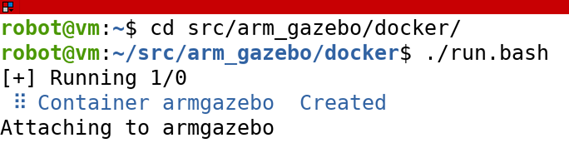

Also retrieve your hostname via command: hostname -I

### 0.3 Connect MATLAB to Gazebo using the ROS Toolbox

Note: for connections inside Lipscomb's network make sure you have already updated your hosts files by setting the IP address above followed by VM.

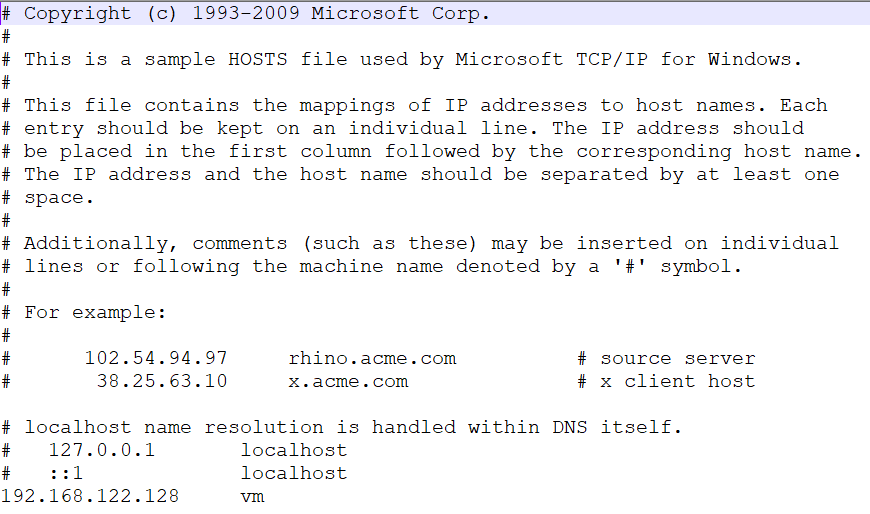r

Once, you have done that, you can simply call rosinit with the IP address of your virtual machine:

rosinit('192.168.56.101');

Initializing global node /matlab_global_node_78930 with NodeURI http://192.168.56.1:55123/ and MasterURI http://192.168.56.101:11311.


# 1 Preliminaries

## 1.1 Matlab Cells

Matlab has a type calls cells that is similar to an array or vector. The only difference is that it can hold variables of different types at the same time.  Arrays cannot do that.

There are a few ways to create a cell

- Use the cell command and assize the size before assigning values

- Set individual elements with curly brackets

- Set an entire cell array at once

1. Cell command

a = cell(1,3) % Instantiate a as a cell with a pre-determined size

a = 1×3 cell array
    {0×0 double}    {0×0 double}    {0×0 double}


% Set the values
a{1} = 1; 
a{2} = 'foo';
a{3} = [1,2,3]; % fill different elements via curly brackets

2. Set entire cell at once:

c={1,'foo', [1,2,3]};

How can we access the elemnts of a cell access?

There are 2 methods:

- {} gives you access to the inside data

- () gives you access to the cell 

% Retrieve the elements. Two methods:
a(1) % will show you a cell with the data structure/type inside

ans = 1×1 cell array
    {[1]}


a{1} % enters the cell and directly gives you data inside

ans = 1

c{3} % Same here but you see the array

ans =      1     2     3


## 1.2 TF Messages

Once the ROS network is running, the poses of each of the frames is available via the tf tree. 

The TF tree can be captured by creating a rostf object:

tftree = rostf('DataFormat','struct')

tftree =   TransformationTree with properties:

    AvailableFrames: {0×1 cell}
     LastUpdateTime: [0×1 struct]
         BufferTime: 10
         DataFormat: 'struct'


With this tftree object, you can see all available frames in the network:

tftree.AvailableFrames

ans = 25×1 cell array
    {'base'                               }
    {'base_link'                          }
    {'base_link_inertia'                  }
    {'camera_depth_link'                  }
    {'camera_link'                        }
    {'flange'                             }
    {'forearm_link'                       }
    {'gripper_tip_link'                   }
    {'robotiq_85_base_link'               }
    {'robotiq_85_left_finger_link'        }
    {'robotiq_85_left_finger_tip_link'    }
    {'robotiq_85_left_inner_knuckle_link' }
    {'robotiq_85_left_knuckle_link'       }
    {'robotiq_85_right_finger_link'       }
    {'robotiq_85_right_finger_tip_link'   }
    {'robotiq_85_right_inner_knuckle_link'}
    {'robotiq_85_right_knuckle_link'      }
    {'robotiq_coupler'                    }
    {'shoulder_link'                      }
    {'tool0'                              }
    {'upper_arm_link'                     }
    {'world'                              }
    {'wris

Finally, we can get the transform we desire by calling `getTransform `along inputs:

- tftree object

- targetgrame: this is your reference frame

- sourceframe: 

tform = getTransform(tftree,'base','gripper_tip_link',rostime('now'), 'Timeout', 2);

This tform will contain the translation and rotation. 

t=tform.Transform.Translation

t = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              X: -0.0979
              Y: -0.1343
              Z: 0.7128


R=tform.Transform.Rotation

R = struct with fields:
    MessageType: 'geometry_msgs/Quaternion'
              X: 0.0018
              Y: -0.7061
              Z: 3.2322e-04
              W: -0.7081


Or see the entire message:

rosShowDetails(tform)

ans =     '
       MessageType  :  geometry_msgs/TransformStamped
       Header          
         MessageType :  std_msgs/Header
         Seq         :  0
         Stamp          
           Sec  :  18
           Nsec :  30000000
         FrameId     :  base
       ChildFrameId :  gripper_tip_link
       Transform       
         MessageType :  geometry_msgs/Transform
         Translation    
           MessageType :  geometry_msgs/Vector3
           X           :  -0.09792697298877633
           Y           :  -0.1342592935734378
           Z           :  0.7128085935843117
         Rotation       
           MessageType :  geometry_msgs/Quaternion
           X           :  0.001808677543020566
           Y           :  -0.7060637905312503
           Z           :  0.0003232166305413894
           W           :  -0.7081458521499635'


How can we verify this transformation? RVIZ is helpful in this context.

To open RVIZ, go to your linux terminal and do the following:

01 Open a pseudo-terminal inside the Docker container with the following command:

`docker exec -it armgazebo tmux`

02 Go to the directory where there is a pre-configfured RVIZ file:

`cd src/arm_gazebo/config`

03 Run the following ROS command to start rviz:

`rosrun rviz rviz -d view.rviz`

04 Add a RobotModel viewer

`Click Add, Select RobotModel`

05 Only show base and gripper_tip_links

`Go to TF viewer, expand Frames menu, unclick 'All Enabled', only select base and gripper_tip_link`

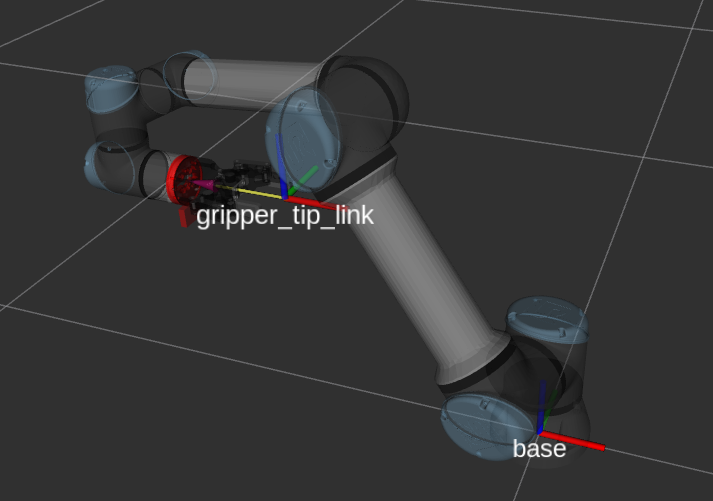

## 1.3 Trajectory Messages

Soon we will be using some new ROS types that will help us generate trajectories within ROS. 

These types belong the trajectory_msgs library. There are two types we will be working with:

- JointTrajectory

- JointTrajectoryPoints

JointTrajectoryPoints represents the positions and time of a waypoint in a trajectory.

JointTrajectory then takes JointTrajectoryPoints to form a vector of points (in addition to the name of the joints themselves --aka think UR5e joint names)

% Create individual points at specific times (1sec, 2sec).
a = rosmessage('trajectory_msgs/JointTrajectoryPoint', 'DataFormat', 'struct')

a = struct with fields:
      MessageType: 'trajectory_msgs/JointTrajectoryPoint'
        Positions: [0×1 double]
       Velocities: [0×1 double]
    Accelerations: [0×1 double]
           Effort: [0×1 double]
    TimeFromStart: [1×1 struct]


a.TimeFromStart = rosduration(1, 'DataFormat','struct');
a.Positions=ones(1,3);

b = rosmessage('trajectory_msgs/JointTrajectoryPoint', 'DataFormat', 'struct')

b = struct with fields:
      MessageType: 'trajectory_msgs/JointTrajectoryPoint'
        Positions: [0×1 double]
       Velocities: [0×1 double]
    Accelerations: [0×1 double]
           Effort: [0×1 double]
    TimeFromStart: [1×1 struct]


b.TimeFromStart = rosduration(2,'DataFormat','struct');
b.Positions=2*ones(1,3);

% Add these points to a trajectory
c = rosmessage('trajectory_msgs/JointTrajectory', 'DataFormat', 'struct')

c = struct with fields:
    MessageType: 'trajectory_msgs/JointTrajectory'
         Header: [1×1 struct]
     JointNames: {0×1 cell}
         Points: [0×1 struct]



% Has a Points vector of structure. Assign by elements with parenthesis:
c.Points=[a,b] % Could be done individually as c.Points(1)=a; c.Points(2)=b;

c = struct with fields:
    MessageType: 'trajectory_msgs/JointTrajectory'
         Header: [1×1 struct]
     JointNames: {0×1 cell}
         Points: [1×2 struct]



% Set JointNames as a cell of strings
c.JointNames={'joint1','joint2','joint3'}

c = struct with fields:
    MessageType: 'trajectory_msgs/JointTrajectory'
         Header: [1×1 struct]
     JointNames: {'joint1'  'joint2'  'joint3'}
         Points: [1×2 struct]


### 1.4 Dictionaries

We can make use of dictionaries to always retrieve the right index value for a given joint robot name. 

Dictionaries are structures that connect a key to a value. The key in this case can be a string denoting the joint name of the robot to its index value. 

 robot = dictionary('q1',1,...
                        'q2',2,...
                        'q3',3);

Once the dictionary is created, a simple way to use it, is to pass a key to it (i.e. in the form a string name) using parenthesis and retrive it's value (i.e. the index value):

 idx = robot('q3')

idx = 3

# 2. ROS Actions - Controlling a Gripper Using ROS Action Client

As with ROS services, there is a server and a client. In this case we call them:

- The action server, and 

- The action client.

The action server will use an **action topic** along with an **action message** type. 

In this section, we will learn about Action Clients by controlling the UR5e robotic gripper:

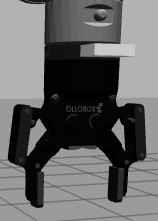

# **2.1.1 Action Servers**

Action Servers, like Service Servers, take an action topic, an action type, and a callback function to define their behavior. They are created via `rosactionserver`:

    `SERVER = rosactionserver(ACTIONNAME,ACTIONTYPE,ExecuteGoalFcn=CB,'DataFormat','struct')`

We will not spend much time studying action servers and callbacks at this point. But I will leave you to explore the documentation to gain further insights on your own at this time:

help rosactionserver 

 rosactionserver - Create ROS Action Server
    Use rosactionserver to create an action server as a SimpleActionServer
    object.

    Syntax
      server = rosactionserver(actionname,actiontype,ExecuteGoalFcn=cb)
      [server] = rosactionserver(___,"DataFormat","struct")

      server = ros.SimpleActionServer(node, actionname,actiontype,ExecuteGoalFcn=cb)
      [server] = ros.SimpleActionServer(___,DataFormat="struct")

    Examples
      Create ROS Action Server and Execute Goal
      Create Custom Callback for a ROS Action Server Using the Predefined Callback Framework

    See also rosActionServerExecuteGoalFcn, rosactionclient,
      

# 2.1.2 ROS Action Helper Functions

Find out which Actions exist in the network:

rosaction list 

Find out particular info on an action:

rosaction info /pos_joint_traj_controller/follow_joint_trajectory

Or more succinctly the type:

rosaction type /pos_joint_traj_controller/follow_joint_trajectory

Lets explore clients.

# **2.2. Action Clients**

Action clients, like Service clients, will send out a message, with two possibles kinds of requests:

- A goal, or

- A cancellation request

After the Action Server receives the message, it will return three things:

- status:             list of pre-determined status' like (pending, active, preempted, **succeeded**, aborted, rejected, preempting, rejected, recalling, lost).

- feedback:        intermediate outputs 

- result.              a custom message you want the user to read for both success, failure, and cancellation scenarios.

Remember that actions are *long term* tasks. The Action server will return **status** updates when an event happens (success or some kind of failure). There will also be intermediate **feedback** as the Server executes the command. Result messages prints upon success, failure, or cancellation. Typically there is a default message, but this can be overriden in the callback.

Action clients can be called via `rosactionclient`:

`    CLIENT = rosactionclient(ACTIONNAME)`

# **2.3. Action Messages and action helper functions**

Actions have a new helper function that we can use to extract information about actions in the network. The helper method is: `rosaction` (it has sub-calls to list, get info, and type). 

You can run the helper function to see the actions in our ROS network:

rosaction list

Note: there are only two actions running.

- Gripper: /gripper_controller/follow_joint_trajectory

- Robot Arm: /pos_joint_traj_controller/follow_joint_trajectory

Let's also begin by exploring the type for the gripper action via the `rosaction type /action_topic` call:

rosaction type /gripper_controller/follow_joint_trajectory

We learn the type of the action topic is: `control_msgs/FollowJointTrajectory`

`Follow Joint Trajectory`

This type is very important in ROS. It takes the positions and/or velocities and/or forces at a particular time.

Typically an action server would take these points and basically use the equivalent of tpoly to create smooth trajectories. 

Points along the trajectory would in turn be sent to a controller to execute the points. 

### `Action Messages (i.e. control_msgs/FollowJointTrajectory)`

If you want to analyze the structure of `control_msgs/FollowJointTrajectory` via rosmessage, you will get an error:

rosmessage('control_msgs/FollowJointTrajectory')

Now, if you use <tab> to extend the type of `control_msgs/FollowJointTrajectory `you will find 7 messages of this type. 

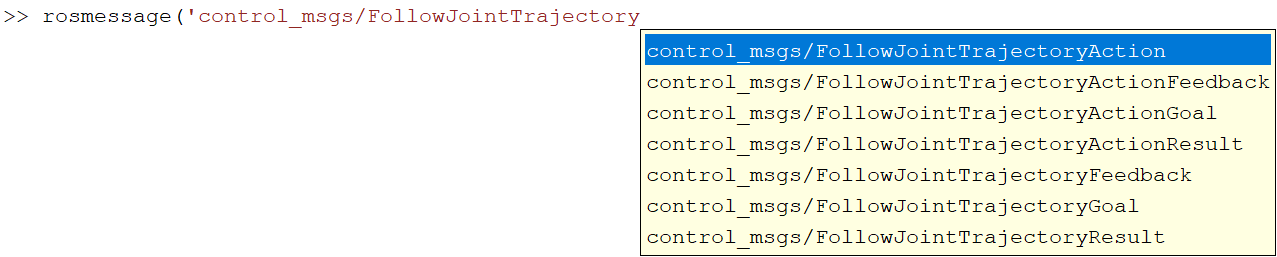

So how does it all work?

I provide a detailed description below. It is possible for you to skip the next section and jump directly to section 4. Gripper Action Client Example for an example. 

But the information below is useful to understand details. 

Action messages are more complex than service messages since they must contain information for goal, feedback, and result. 

All action messages have a:

- Generalize type (in this case Action), which defines the 'interface'. 

- Granular (goal, feedback, and result) messages, and 

- Larger actionGoal/actionFeedback/actionResult messages which have the individual goal/feedback/result in **addition** to extra metadata. 

#### A. Generic Interface message

rosmessage('control_msgs/FollowJointTrajectoryAction')

It tells us we have high-level **ActionGoal**, **ActionResult**, and **ActionFeedback** sub-message types. 

And granular **Goal**, **Result**, and **Feedback** sub-message types. 

I visualize their main relationships here:

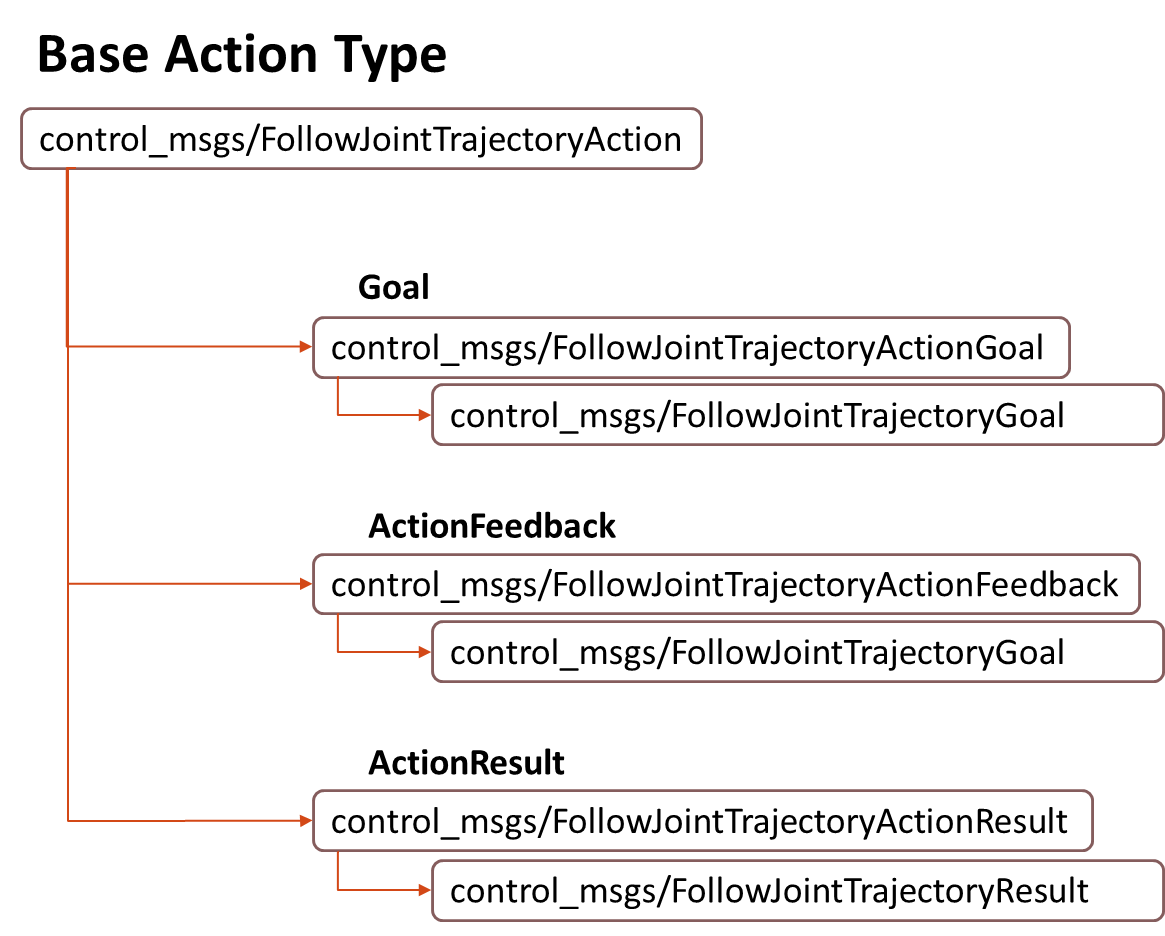 

**Structure of Granular Types**

Below you can find the structure of the granular messages:

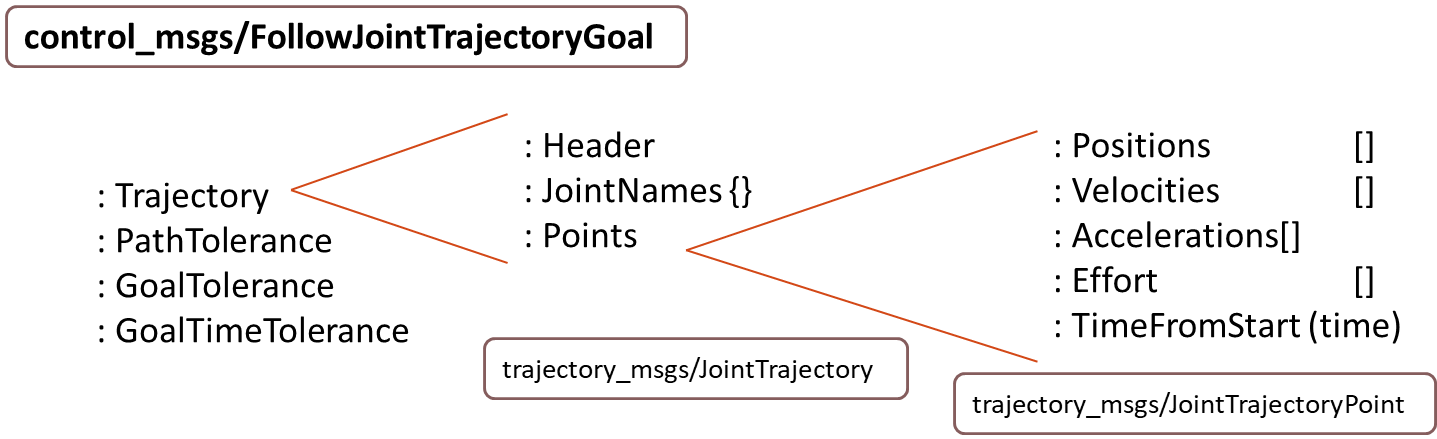

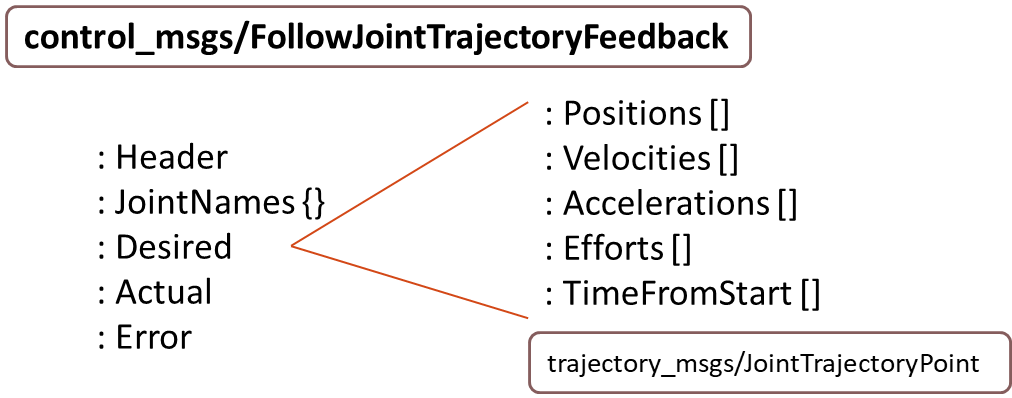

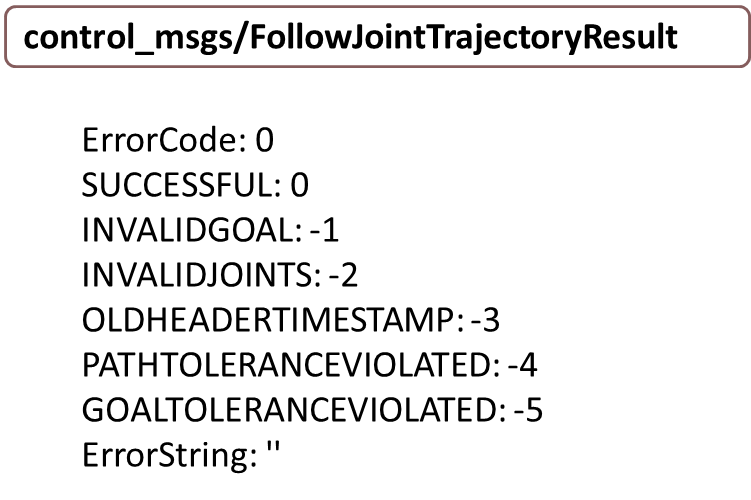

#### B.1 Granular *Goal *Type

Let's explore the granular `control_msgs/FollowJointTrajectoryGoal` type:

g=rosmessage('control_msgs/FollowJointTrajectoryGoal', 'DataFormat','struct')

It contains Trajectory along with 3 different tolerance options. Trajectory will be the most critical for you:

g.Trajectory

Trajectory in turn is a structure that contains two sub-fields:

- JointNames: it's a array/cell of names of the joints

- Points: a structure of type 'JointTrajectoryPoints' which allows you to further enter positions or velocities, or accelerations, or efforts (forces/torques), and a time from start:

g.Trajectory.Points

#### B.2 Granular Feedback Type

Let's explore the granular `control_msgs/FollowJointTrajectoryFeedback` type used to get intermediate results:

f=rosmessage('control_msgs/FollowJointTrajectoryFeedback', 'DataFormat','struct')

In this type, you can include your original goal for each desired joint (it would be written on the server side, which we will not cover), along with actual, and error. This will give you an idea of how things evolve over time. 

Desired, Actual, and Error are of type `trajectory_msgs/JointTrajectoryPoint` that we visited before in goal and can take names, positions, etc.

f.Desired

#### B.3 Granular Result Type

Let's explore the granular `control_msgs/FollowJointTrajectoryResult` type used to get result information:

r=rosmessage('control_msgs/FollowJointTrajectoryResult', 'DataFormat','struct')

Here, the error code will be set to a number between 0 to -5. Where each number indicates a particular outcome. You can also set an error-string. This would again all be set in the callback.

Now that we have finished looking at the granular messages, let's look at one of the meta-messages.

#### C.1 Meta Goal Type: ActionGoal

Let's explore the meta `control_msgs/FollowJointTrajectoryActionGoal` which on top of the goal will include meta information:

ag=rosmessage('control_msgs/FollowJointTrajectoryActionGoal', 'DataFormat','struct')

This message has a field for the *granular* goal we saw before. 

ag.Goal

In addition to that, it has a `GoalId `structure to capture a string for the goal and a stamp for time.

ag.GoalId

#### C.2 Meta Goal Type: ActionFeedback and ActionResult

I group the ActionFeedback and ActionResult because both of them have the same extra meta-data. 

Let's look at the meta `control_msgs/FollowJointTrajectoryActionFeedback` which includes the extra *Status* information:

af=rosmessage('control_msgs/FollowJointTrajectoryActionFeedback', 'DataFormat','struct')

Note the same granular feedback structure from before. Header and Status are additional:

Status has status types specifically related to feedback/result, which would be set in the callback

af.Status

# 2.4. Gripper Action Client Example 

Let's jump into an example to see how we might create a client, set a goal, and call the action server.  

Create a client based on the action topic` /gripper_controller/follow_joint_trajectory` and type `control_msgs/FollowJointTrajectory as a struct:`

grip_client = rosactionclient('/gripper_controller/follow_joint_trajectory',...
                              'control_msgs/FollowJointTrajectory', ...
                              'DataFormat', 'struct')

This create a SimpleActionClient object. 

Create Goal Message: 

As with services, pass the client object type to instantiate:

gripGoal = rosmessage(grip_client)

We will soon populate gripGoal. Start by creating a variable that sets the displacement of the fingers. 0 displacement = open. 0.8 displacement = closed. 0.4 would be half-way.

- To open fingers set gripPos to 0

- To close fingers set gripPos to 0.8

gripPos = 0.1 %0 is fully open, 0.8 is fully close

Populate the Trajectory goal

- The next step is to fill the relevant parts of the control_msg/FollowJointTrajectoryGoal. 

- Tolerances, Names, Points, and time stamp. It's cleaner to do it via a function (make sure you did git pull AND add new folders to Matlab Path) 

gripGoal = packGripGoal(gripPos,gripGoal)

Now that we have finalized populating the ROS action client message, let's send it. 

You can bring your gripper into view to see how the command will affect your robot gripper:

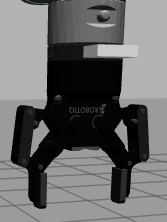

% Send
timeOut = 2; % secs
try waitForServer(grip_client,timeOut)
    disp('Connected to action server. Sending goal...')
    [res,state,status] = sendGoalAndWait(grip_client,gripGoal,timeOut);
catch
    % Re-attempt when netork potential errors arise
    disp('First try failed... Trying again...');
    [res,state,status] = sendGoalAndWait(grip_client,gripGoal,timeOut);
end 

Notice the 3 outputs:

- Status: 'goal active'

- Result: ErrorCode = 0 (implies success)

- Feedback: i.e. desired position (0.8), current (0), error or difference (0.8)

### Summary

In summary, we achieved this with 5 lines of code (where the packGripGoal is the most elaborate function).

grip_client = rosactionclient('/gripper_controller/follow_joint_trajectory',...
                              'control_msgs/FollowJointTrajectory',...
                              'DataFormat', 'struct');
gripGoal    = rosmessage(grip_client);
gripPos     = 0.4;
gripGoal    = packGripGoal(gripPos,gripGoal);
sendGoal(grip_client,gripGoal);

# 3. Controlling the Robot Arm Pose using the ROS Action Client

We now repeat the same process to establish the waypoints for the robot arm. 

### Initialize ROS Action Client

trajAct = rosactionclient('/pos_joint_traj_controller/follow_joint_trajectory',...
                          'control_msgs/FollowJointTrajectory',...
                          'DataFormat', 'struct') 

trajAct =   SimpleActionClient with properties:

           ActionName: '/pos_joint_traj_controller/follow_joint_trajectory'
           ActionType: 'control_msgs/FollowJointTrajectory'
    IsServerConnected: 0
                 Goal: [1×1 struct]
            GoalState: ''
        ActivationFcn: @(~)disp('Goal active')
          FeedbackFcn: @(~,msg)disp(['Feedback: ',showDetailsAnyFormat(msg)])
            ResultFcn: @(~,res)disp(['Final state ',res.State,' with result: ',showDetailsAnyFormat(res.Message)])
           DataFormat: 'struct'


Instantiate the goal

trajGoal = rosmessage(trajAct)

trajGoal = struct with fields:
          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 struct]
        PathTolerance: [0×1 struct]
        GoalTolerance: [0×1 struct]
    GoalTimeTolerance: [1×1 struct]


trajAct.FeedbackFcn = []; 

Let's get information about where the robot is currently by looking at the joint configuration. 

Let's create a subscriber to the `/joint_states topic`.

jointSub = rossubscriber("/joint_states")

jointSub =   Subscriber with properties:

                      TopicName: '/joint_states'
                  LatestMessage: [0×1 JointState]
                    MessageType: 'sensor_msgs/JointState'
                     BufferSize: 1
    MessagePreprocessingEnabled: 0
                  NewMessageFcn: []
                     DataFormat: 'object'


Now, let's receive the data and use it to compute the IKs and get the pose of the end-effector. Note, the order of joints occurs according to Name: {elbow,finger,lift,pan,w1,w2,w3}.

jointStateMsg = jointSub.LatestMessage

jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


### Setup Robot Model for Inverse Kinematics

We will follow the familar commands we have run in the past to compute IKs. With one caveat. The UR5 model in Gazebo Forward kinematics are slightly different and need to be updated. We won't worry about the details.

The ROS Action that controls the robot uses the position of the individual joints as an input. In roder to make it easier to establish a cartesian target location it is necessary to have a robot model for which to [calculate the inverse kinmetics.](https://www.mathworks.com/help/robotics/ref/inversekinematics-system-object.html)

UR5e = loadrobot('universalUR5e', DataFormat="row")

UR5e =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'row'


#### Minor Adjustments between ROS URDF robot model and Gazebo

Adjust the forward kinematics to match the URDF model in Gazebo:

tform=UR5e.Bodies{3}.Joint.JointToParentTransform;    
UR5e.Bodies{3}.Joint.setFixedTransform(tform*eul2tform([pi/2,0,0]));

tform=UR5e.Bodies{4}.Joint.JointToParentTransform;
UR5e.Bodies{4}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));

tform=UR5e.Bodies{7}.Joint.JointToParentTransform;
UR5e.Bodies{7}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));

#### Create the numerical IK solver

ik = inverseKinematics("RigidBodyTree",UR5e); % Create Inverse kinematics solver

Set IK weights

ikWeights = [0.25 0.25 0.25 0.1 0.1 .1]; % configuration weights for IK solver [Translation Orientation] see documentation

Before proceeding, get the latest joint angles of the robot by calling `receive` (blocking function).

jointStateMsg = receive(jointSub,3) % receive current robot configuration

jointStateMsg =   ROS JointState message with properties:

    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 Header]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]

  Use showdetails to show the contents of the message


#### Setting the Initial IK Guess

The initial guess will be the current arm configuration. 

Start by creating an empty row vector using `homeConfiguration`.

initialIKGuess = homeConfiguration(UR5e)

initialIKGuess =      0     0     0     0     0     0


One thing to be careful is to copy the correct order from jointStateMsg.Position to our structure initialIKGuess. 

To know the order, look at the names:

jointStateMsg.Name

ans = 7×1 cell array
    {'elbow_joint'                  }
    {'robotiq_85_left_knuckle_joint'}
    {'shoulder_lift_joint'          }
    {'shoulder_pan_joint'           }
    {'wrist_1_joint'                }
    {'wrist_2_joint'                }
    {'wrist_3_joint'                }


So, order is: 

- elbow:3

- knuckle: 7

- lift: 2

- pan:1

- wrist1: 4

- wrist2: 5

- wist3:6 

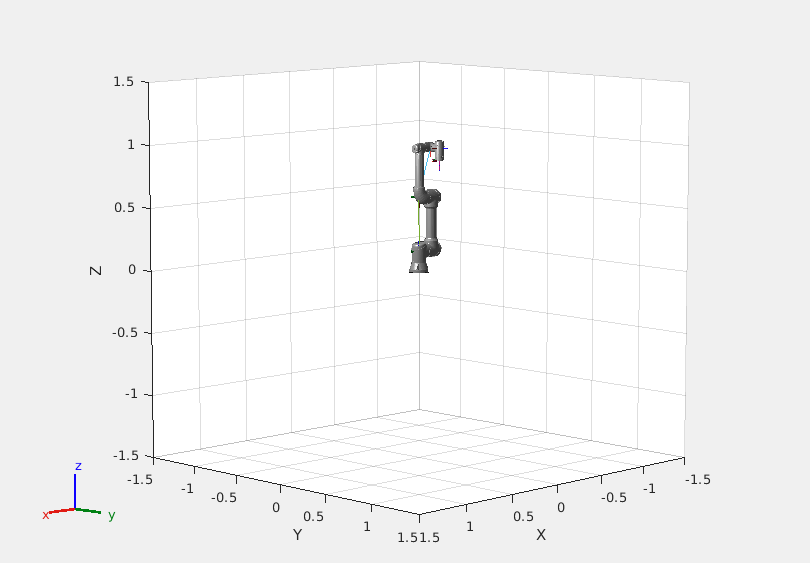

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


% update configuration in initial guess
initialIKGuess(1) = jointStateMsg.Position(4);  % Shoulder Pan
initialIKGuess(2) = jointStateMsg.Position(3);  % Shoulder Tilt
initialIKGuess(3) = jointStateMsg.Position(1);  % Elbow
initialIKGuess(4) = jointStateMsg.Position(5);  % W1
initialIKGuess(5) = jointStateMsg.Position(6);  % W2
initialIKGuess(6) = jointStateMsg.Position(7);  % W3
show(UR5e,initialIKGuess)

### Set End-Effector Pose

Once we have our ik object and initial guess, we need a goal pose for which to compute the joint angles.

Use the interactive controls below to set a cartesian position of the robot end-effector and use the inverse kinematics solver to determine a robot configuration.

gripperX = 0.8;
gripperY = -0.04;
gripperZ = 0.15;

gripperTranslation = [gripperY gripperX gripperZ];
gripperRotation    = [-pi/2 -pi 0]; %  [Z Y Z] radians


tform = eul2tform(gripperRotation); % Matlab eul2tform or Peter Corke's eul2tr(gripperRotation)
tform(1:3,4) = gripperTranslation'; % Set translation in homogeneous transform converted from ROS to MATLAB order

Finally, compute the IKs:

[configSoln, solnInfo] = ik('tool0',...     % from base to tool0
                            tform, ...      % goal homogenoues transform
                            ikWeights, ...  % IK optimization weights
                            initialIKGuess) % Current joint angles

configSoln =    -0.1172    1.9735   -1.1060   -0.8675   -0.0000   -1.6880


solnInfo = struct with fields:
           Iterations: 52
    NumRandomRestarts: 0
        PoseErrorNorm: 9.1383e-10
             ExitFlag: 1
               Status: 'success'


Visualize your solution to make sure it makes sense:

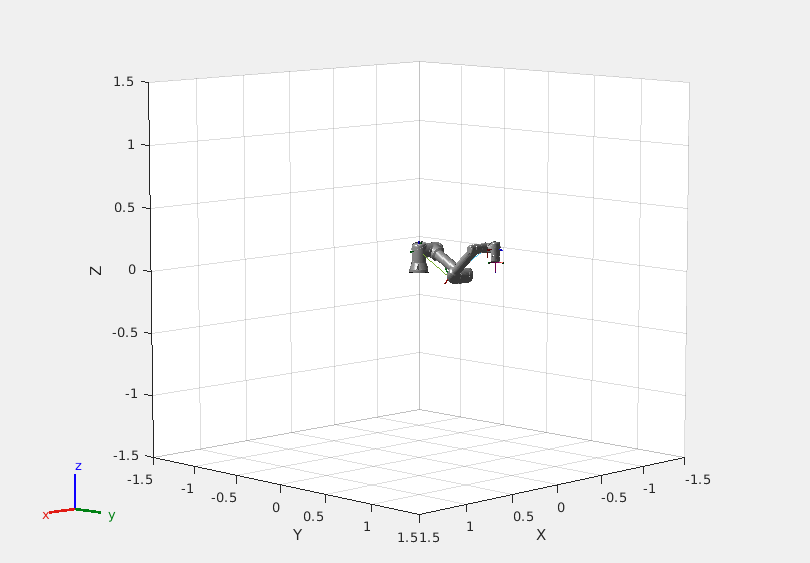

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(UR5e,configSoln)

### Send Joint Trajectory Goal 

Before sending the goal, we need to convert from MATLAB structure to ROS structure. 

We need to follow the order we established earlier: 

- elbow (3)

- lift (2)

- pan (1)

- wrist1 (4)

- wrist2 (5)

- wist3 (6)

UR5econfig = [configSoln(3)... 
              configSoln(2)...
              configSoln(1)...
              configSoln(4)...
              configSoln(5)...
              configSoln(6)]

UR5econfig =    -1.1060    1.9735   -0.1172   -0.8675   -0.0000   -1.6880


Let's use a packing function to appropriately fill names and positions:

trajGoal = packTrajGoal(UR5econfig,trajGoal)

trajGoal = struct with fields:
          MessageType: 'control_msgs/FollowJointTrajectoryGoal'
           Trajectory: [1×1 struct]
        PathTolerance: [0×1 struct]
        GoalTolerance: [0×1 struct]
    GoalTimeTolerance: [1×1 struct]


Send to the action server:

sendGoalAndWait(trajAct,trajGoal)

Invalid or deleted object.

Error in ros.SimpleActionClient/sendGoalAndWait (line 484)
            timeout = obj.Parser.parseSendGoalAndWaitInput(defaultTimeout, obj.GoalMessageType, ...

Note:

- We do not have an optimal arm configuration. We could try to change the starting configuration by controlling the joint angles directly and try again. 

- We start to think about collisions - this will go into motion planning later.

- We need to get a model's pose reach it at a good angle and close the gripper. 

HW

- Edit actions/action_pick_place.m to make pick work for specific models rCan2 

- Complete place on your own. 

- You will need to save your code in your own Github repository

- Fork my repo into your own

# 4. Receive Camera Image Using ROS Subscriber

rgbImgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");
pause(1)
curImage = receive(rgbImgSub,3);
rgbImg = rosReadImage(curImage); 
imshow(rgbImg)

# 5. Receive Depth Image Using ROS Subscriber

rgbDptSub = rossubscriber('/camera/depth/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
curDepth = receive(rgbDptSub,3);
depthImg = rosReadImage(curDepth); 
imshow(depthImg)

# 6. Appendix - Utilities

This section contains two functions that can be reused for packing the goal information for the ROS action goals to the appropriate message structures.

function gripGoal=packGripGoal(pos,gripGoal)
    jointWaypointTimes = 0.1;                                                 % Duration of trajectory
    jointWaypoints = [pos]';                                                % Set position of way points
    numJoints = size(jointWaypoints,1);                                     % Only 1 joint for gripper

    % Joint Names --> gripGoal.Trajectory
    gripGoal.Trajectory.JointNames = {'robotiq_85_left_knuckle_joint'};

    % Goal Tolerance: set type, name, and pos/vel/acc tolerance
    gripGoal.GoalTolerance = rosmessage('control_msgs/JointTolerance','DataFormat', 'struct');

    gripGoal.GoalTolerance.Name = gripGoal.Trajectory.JointNames{1};
    gripGoal.GoalTolerance.Position = 0;
    gripGoal.GoalTolerance.Velocity = 0.1;
    gripGoal.GoalTolerance.Acceleration = 0.1;
    
    % Create waypoint as a ROS trajectory point type. Time for position will be set to TimeFromStart and then just position via JointWaypoints. t 
    trajPts = rosmessage('trajectory_msgs/JointTrajectoryPoint', 'DataFormat', 'struct');

    trajPts.TimeFromStart = rosduration(jointWaypointTimes,'DataFormat', 'struct');
    trajPts.Positions = jointWaypoints;

    % Zero out everything else
    trajPts.Velocities      = zeros(size(jointWaypoints));
    trajPts.Accelerations   = zeros(size(jointWaypoints));
    trajPts.Effort          = zeros(size(jointWaypoints));
    
    % Copy trajPts --> gripGoal.Trajectory.Points
    gripGoal.Trajectory.Points = trajPts;
end

function trajGoal = packTrajGoal(config,trajGoal)
    jointWaypointTimes = 1;
    jointWaypoints = config';
    numJoints = size(jointWaypoints,1);
    
    trajGoal.Trajectory.JointNames = {'elbow_joint','shoulder_lift_joint','shoulder_pan_joint','wrist_1_joint','wrist_2_joint','wrist_3_joint'};
    
    %for idx = 1:numJoints

    % trajGoal.GoalTolerance = rosmessage('control_msgs/JointTolerance','DataFormat', 'struct');
    % 
    % trajGoal.GoalTolerance.Name = trajGoal.Trajectory.JointNames{1};
    % trajGoal.GoalTolerance.Position = 0;
    % trajGoal.GoalTolerance.Velocity = 0;
    % trajGoal.GoalTolerance.Acceleration = 0;

    %end
    
    trajPts = rosmessage('trajectory_msgs/JointTrajectoryPoint','DataFormat', 'struct');
    trajPts.TimeFromStart = rosduration(jointWaypointTimes, 'DataFormat','struct');
    trajPts.Positions = jointWaypoints;
    trajPts.Velocities = zeros(size(jointWaypoints));
    trajPts.Accelerations = zeros(size(jointWaypoints));
    trajPts.Effort = zeros(size(jointWaypoints));
    
    trajGoal.Trajectory.Points = trajPts;
end